## Set the AWS default region. Code won't run without this.

setenv('AWS_DEFAULT_REGION','us-west-1')

## Load the FileSets

tstart = tic;
load('s3://childmind/matlab/FileSet_test.mat','-mat','fs_test');
load('s3://childmind/matlab/FileSet_train.mat','-mat','fs_train');
load('s3://childmind/matlab/FileSet_val.mat','-mat','fs_val');
telapsed = toc(tstart) 

telapsed = 50.8862

## Create the datastore

%start timer
tstart = tic;
test_imds = imageDatastore(fs_test, 'FileExtensions','.mat');
train_imds = imageDatastore(fs_train, 'FileExtensions','.mat');
val_imds = imageDatastore(fs_val, 'FileExtensions','.mat');
% compute elapsed time 
telapsed = toc(tstart) 

telapsed = 1.0524

## Custom reader function

load_sample = @(x) x.sample; 
readfun = @(x) load_sample(load(x));

test_imds.ReadFcn = readfun;
train_imds.ReadFcn = readfun;
val_imds.ReadFcn = readfun;

## Preview the first sample of the datastore

sample = preview(train_imds);
fprintf('Sample size = %d, %d \n', size(sample));

Sample size = 24, 256 


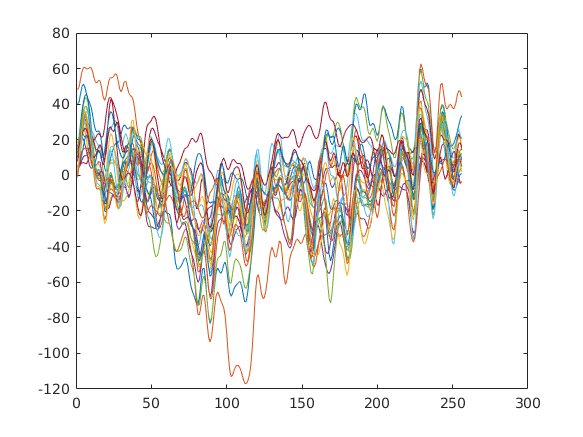

plot(sample');

## Assign labels

%load('s3://childmind/matlab/train_labels.mat','-mat','train_label_info');
load("train_labels.mat",'-mat','train_label_info')
label_col = 3; % column index of desired label, in this case: sex of the subject 
train_labels = categorical(cell2mat(train_label_info(:,label_col)));
train_imds.Labels = train_labels;


%load('s3://childmind/matlab/val_labels.mat','-mat','val_label_info');
load("val_labels.mat",'-mat','val_label_info')
label_col = 3; % column index of desired label, in this case: sex of the subject 
val_labels = categorical(cell2mat(val_label_info(:,label_col)));
val_imds.Labels = val_labels;


%load('s3://childmind/matlab/test_labels.mat','-mat','test_label_info');
load("test_labels.mat",'-mat','test_label_info')
label_col = 3; % column index of desired label, in this case: sex of the subject 
test_labels = categorical(cell2mat(test_label_info(:,label_col)));
test_imds.Labels = test_labels;

## Define the network layers to be trained

channels = [1, 24]; %range of channels 
num_samples = 256; %num of samples
image_size = [channels(2)-channels(1)+1 num_samples 1]; 

num_labels = size(unique(train_imds.Labels),1);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',2, ...
    'MiniBatchSize',70, ...
    'Plots','training-progress',...
    'ValidationData',val_imds);

Train the network

eeg_net = trainNetwork(train_imds,layers,options);

## Testing the trained network

Y_pred = classify(eeg_net,test_imds);

num_test = length(Y_pred);
%Test accuracy
correct = 0;
for i = 1 : num_test
    if(Y_pred(i)==test_imds.Labels(i))
        correct = correct+1;
    end
end

test_accuracy = 100*correct/num_test
%save('Trainednetwork','eeg_net','test_accuracy','options');
